load eigendata.mat;

[i1,i2,i3] = size(images)

i1 = 75

i2 = 256

i3 = 256

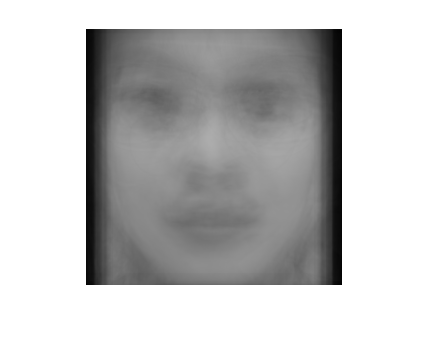

flat_sz = i2*i3;
sum = zeros(1,flat_sz);
for i = 1:i1
    img = images(i,:);
    sum = sum+img;
end
avg = sum / i1;
draw_face(avg,i2,i3);

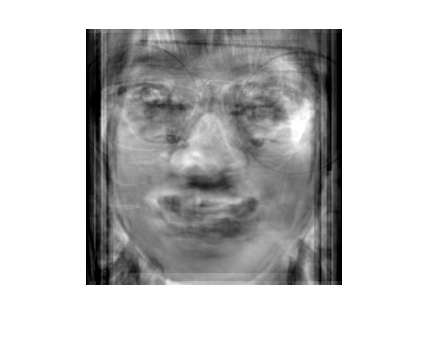

A = zeros(i1,flat_sz);
for i=1:i1
    img = images(i,:);
    diff = img - avg;
    A(i,:) = diff;
end

AAT = A * A';
[V,D] = eig(AAT);
ef = A' * V(:,50) + avg';
draw_face(ef,i2,i3)

function rst = draw_face(vec,N1,N2)
    img = reshape(vec,N1,N2);
    imshow(uint8(img));
end